# Preliminary Data Analysis

addpath('Data\')

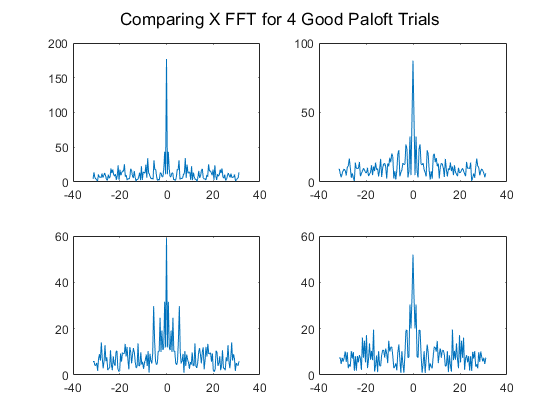

%see x fft of 4 good paloft press trials
[gPaloft1] = get_fft('GPaloft1', 10);
[gPaloft2] = get_fft('GPaloft2', 10);
[gPaloft3] = get_fft('GPaloft3', 10);
[gPaloft4] = get_fft('GPaloft4', 10);
figure();
sgtitle('Comparing X FFT for 4 Good Paloft Trials')
subplot(2,2,1)
plot(gPaloft1(:,1), abs(gPaloft1(:,2)))
subplot(2,2,2)
plot(gPaloft2(:,1), abs(gPaloft2(:,2)))
subplot(2,2,3)
plot(gPaloft3(:,1), abs(gPaloft3(:,2)))
subplot(2,2,4)
plot(gPaloft4(:,1), abs(gPaloft4(:,2)))

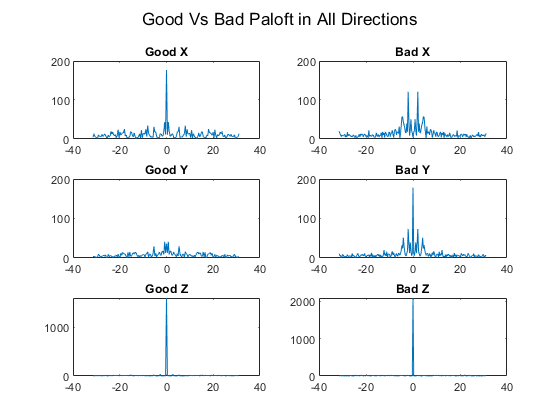

%look at example of good and bad for paloft trial

[bArcPaloft1] = get_fft('BInArcPaloft1', 10);

figure();
sgtitle('Good Vs Bad Paloft in All Directions')
subplot(3,2,1)
plot(gPaloft1(:,1), abs(gPaloft1(:,2)))
title('Good X')
subplot(3,2,2)
plot(bArcPaloft1(:,1), abs(bArcPaloft1(:,2)))
title('Bad X')
ylim([0 200])
subplot(3,2,3)
plot(gPaloft1(:,1), abs(gPaloft1(:,3)))
title('Good Y')
ylim([0 200])
subplot(3,2,4)
plot(bArcPaloft1(:,1), abs(bArcPaloft1(:,3)))
title('Bad Y')
subplot(3,2,5)
plot(gPaloft1(:,1), abs(gPaloft1(:,4)))
title('Good Z')
subplot(3,2,6)
plot(bArcPaloft1(:,1), abs(bArcPaloft1(:,4)))
title('Bad Z')